# Unifying MATLAB and Simulink - Simscape Example

This project implements the workflow described in the blog post series [Unifying MATLAB and Simulink: A User Story](https://blogs.mathworks.com/simulink/2022/04/22/unifying-matlab-and-simulink-a-user-story-part-1/) published on [Guy on SImulink](https://blogs.mathworks.com/simulink/).

This project provides two ways to configure and interact with the model:

- Command-line interface trough `slPart` MATLAB objects

- App developed using App Designer

## Command-line Example

To get started, open the model:

mdl = 'vehicle_SSC';
open_system(mdl);

Define a variable `vehicleObject` used in the 'vehicle" block. 

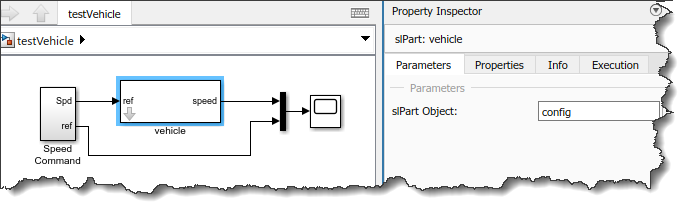

Assign to `vehicleObject` an object from one of the classes in  the `+vehicle` package:

vehicleObject = vehicle.ParallelSUV;

Simulate the model and observe the simulation results through the `vehicleObject` object:

out = sim(mdl);

Parts can have custom visualization

vehicleObject.getLog(out)

ans = slPart vehicle.ParallelSUV
Instantiated in: vehicle_SSC/vehicle

        Engine: [1×1 engine.Engine70kW]
       Battery: [1×1 battery.Battery150Ah]
    Drivetrain: [1×1 drivetrain.Parallel]
          Body: [1×1 body.SUV]

Number of logged signals = 3

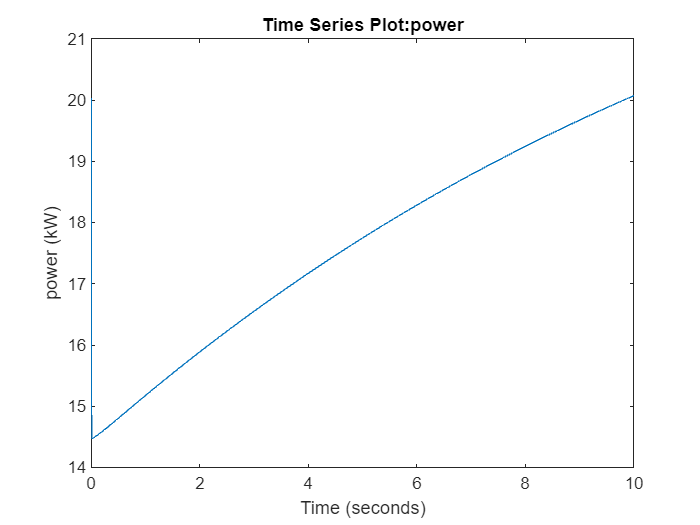

vehicleObject.Battery.plotPower

Simulate the model using a different type of vehicle:

vehicleObject = vehicle.SplitSedan

vehicleObject = slPart vehicle.SplitSedan
Instantiated in: --- unset ---
        Engine: [1×1 engine.Engine50kW]
       Battery: [1×1 battery.Battery100Ah]
    Drivetrain: [1×1 drivetrain.Split]
          Body: [1×1 body.Sedan]

No logged data


vehicleObject.Body = body.CompactSedan;
out = sim(mdl)

out =   Simulink.SimulationOutput:

                logsout: [1x1 Simulink.SimulationData.Dataset] 
                   tout: [276x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


After defining the `vehicleObject` variable, try customizing it:

vehicleObject = vehicle.SplitSedan

vehicleObject = slPart vehicle.SplitSedan
Instantiated in: --- unset ---
        Engine: [1×1 engine.Engine50kW]
       Battery: [1×1 battery.Battery100Ah]
    Drivetrain: [1×1 drivetrain.Split]
          Body: [1×1 body.Sedan]

No logged data


vehicleObject.Body.Mass = vehicleObject.Body.Mass*1.2;
out = sim(mdl)

out =   Simulink.SimulationOutput:

                logsout: [1x1 Simulink.SimulationData.Dataset] 
                   tout: [230x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


## System Configurator App

Open the model, define the `vehicleObject` object and launch the confirutator app: ([Click here to execute the following code](matlab: mdl = 'vehicle_SSC'; open_system(mdl); vehicleObject = vehicle.ParallelSUV; systemConfigurator(mdl)))

This picture should help using the app:

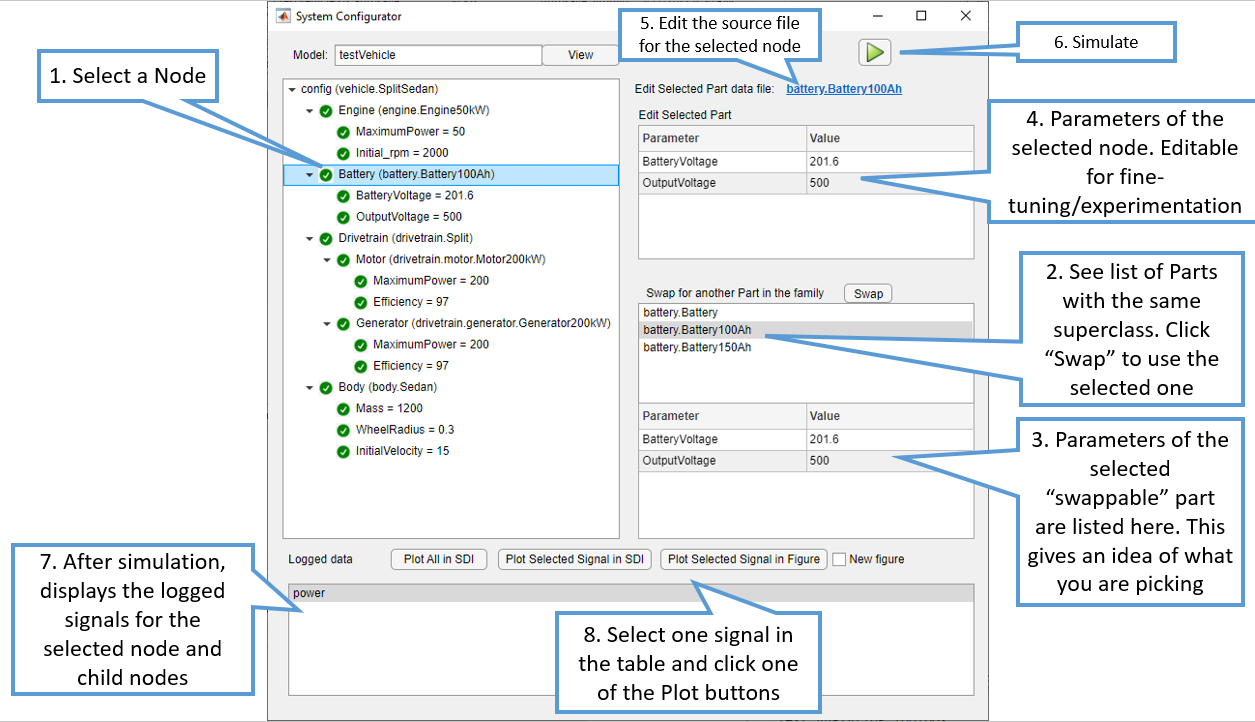

Copyright 2022 The MathWorks, Inc.